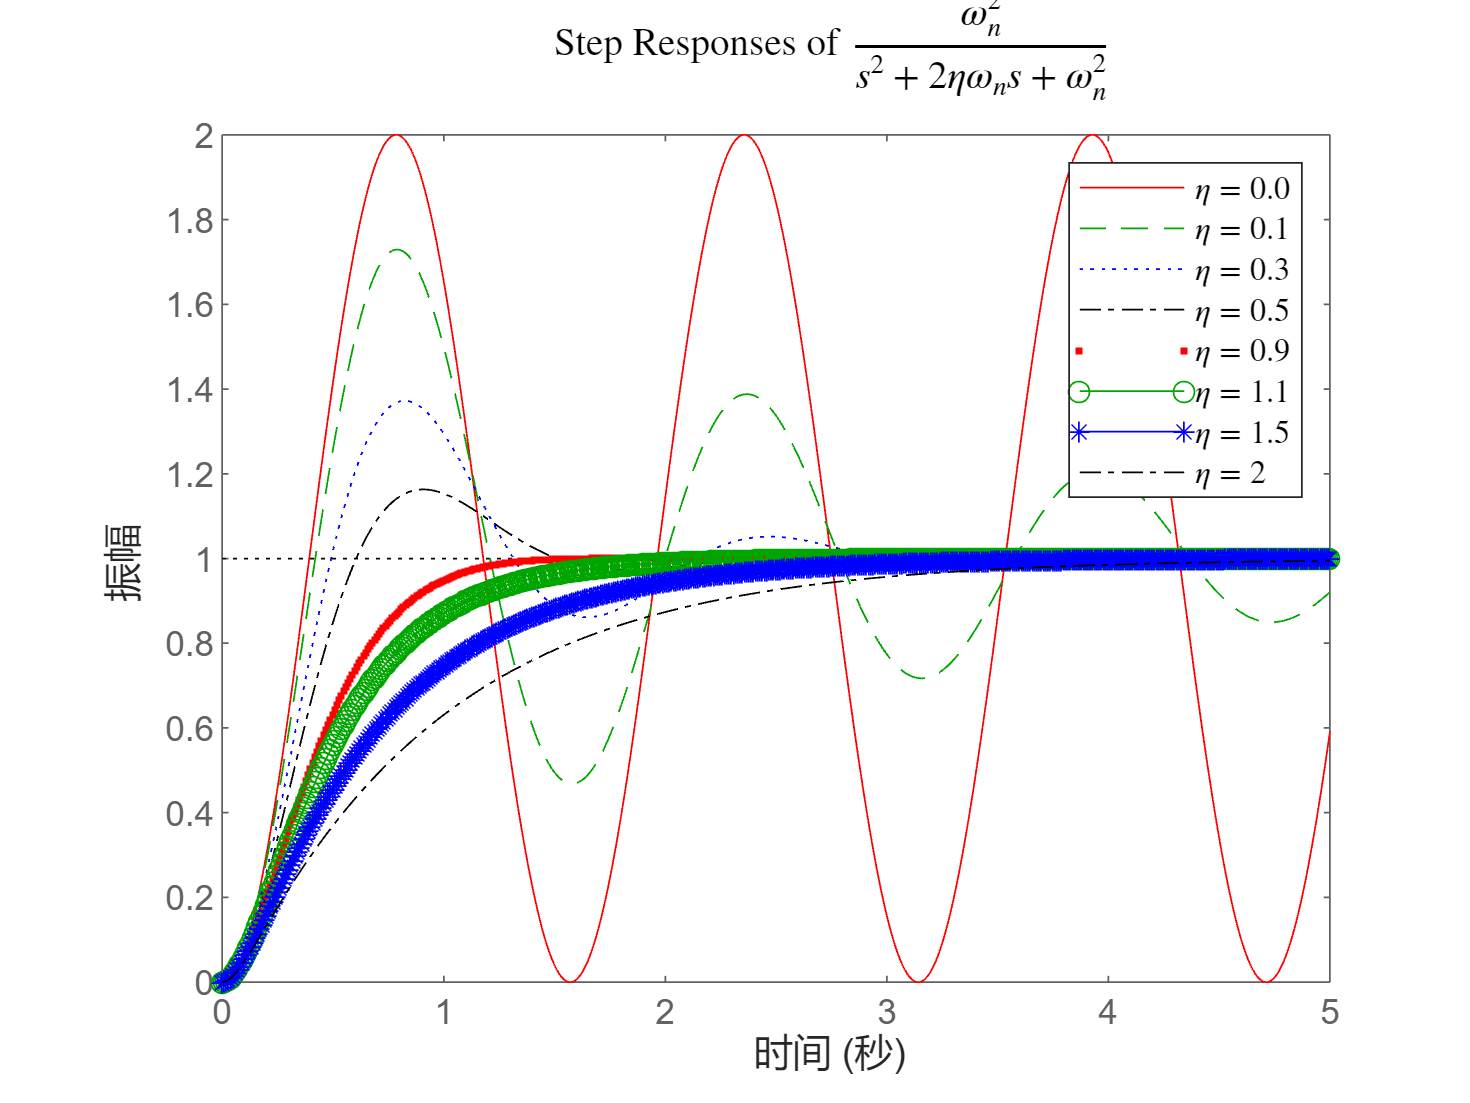

clear all;
close all;
clc;
 
s = tf('s');
t = 0:0.01:5;
wn =4; eta=0.0;
P0 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =4; eta=0.1;
P1 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
 

wn =4; eta=0.3;
P2 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
 

wn =4; eta= 0.5;
P3 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
 

wn =4; eta= 0.9;
P4 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
 

wn =4; eta= 1.1;
P5 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =4; eta= 1.5;
P6 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =4; eta= 2;
P7 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);


figure;
step(P0,'r-', ...
     P1,'g--', ...
     P2,'b:', ...
     P3,'k-.',...
     P4,'r.',...
     P5,'g-o',...
     P6,'b-*',...
     P7,'k-.',t);
 
hh = legend('$\eta = 0.0$','$\eta = 0.1$','$\eta = 0.3$','$\eta = 0.5$','$\eta = 0.9$','$\eta = 1.1$','$\eta = 1.5$','$\eta = 2$');
set(hh,'Interpreter','latex'); 

hh = title('Step Responses of $\frac{\omega_n^2}{s^2+ 2\eta \omega_n s+ \omega_n^2}$');
set(hh,'Interpreter','latex'); 

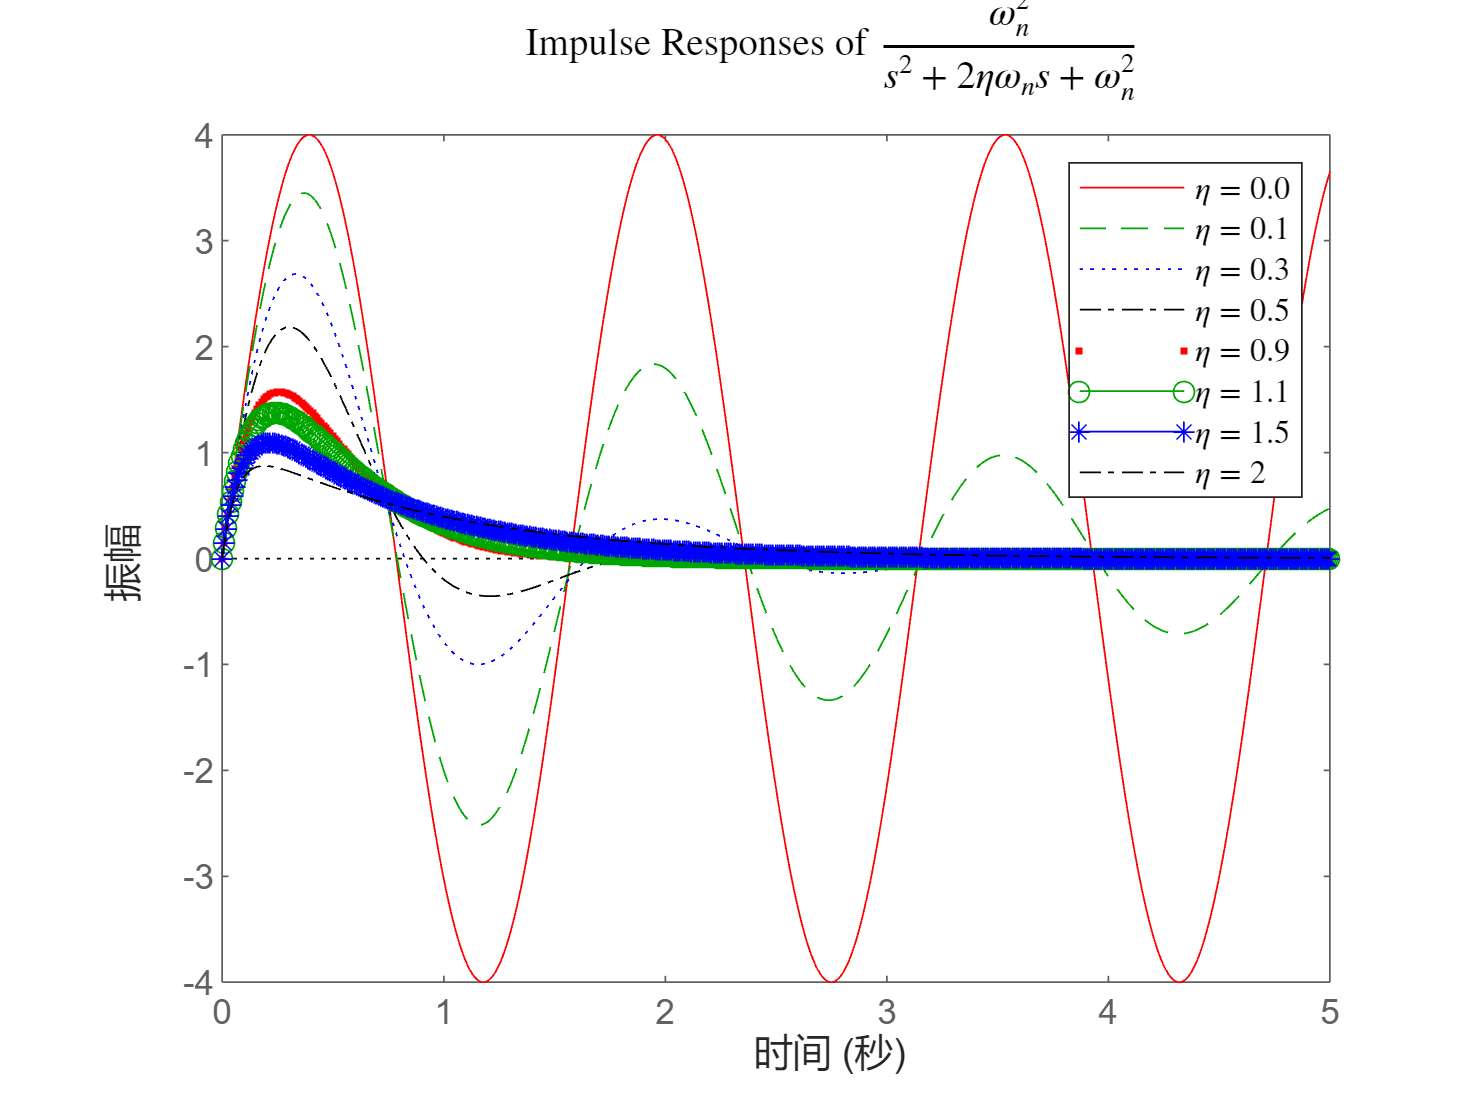

figure;
impulse(P0,'r-', ...
     P1,'g--', ...
     P2,'b:', ...
     P3,'k-.',...
     P4,'r.',...
     P5,'g-o',...
     P6,'b-*',...
     P7,'k-.',t);
hh = legend('$\eta = 0.0$','$\eta = 0.1$','$\eta = 0.3$','$\eta = 0.5$','$\eta = 0.9$','$\eta = 1.1$','$\eta = 1.5$','$\eta = 2$');
set(hh,'Interpreter','latex'); 

hh = title('Impulse Responses of $\frac{\omega_n^2}{s^2+ 2\eta \omega_n s+ \omega_n^2}$');
set(hh,'Interpreter','latex'); 

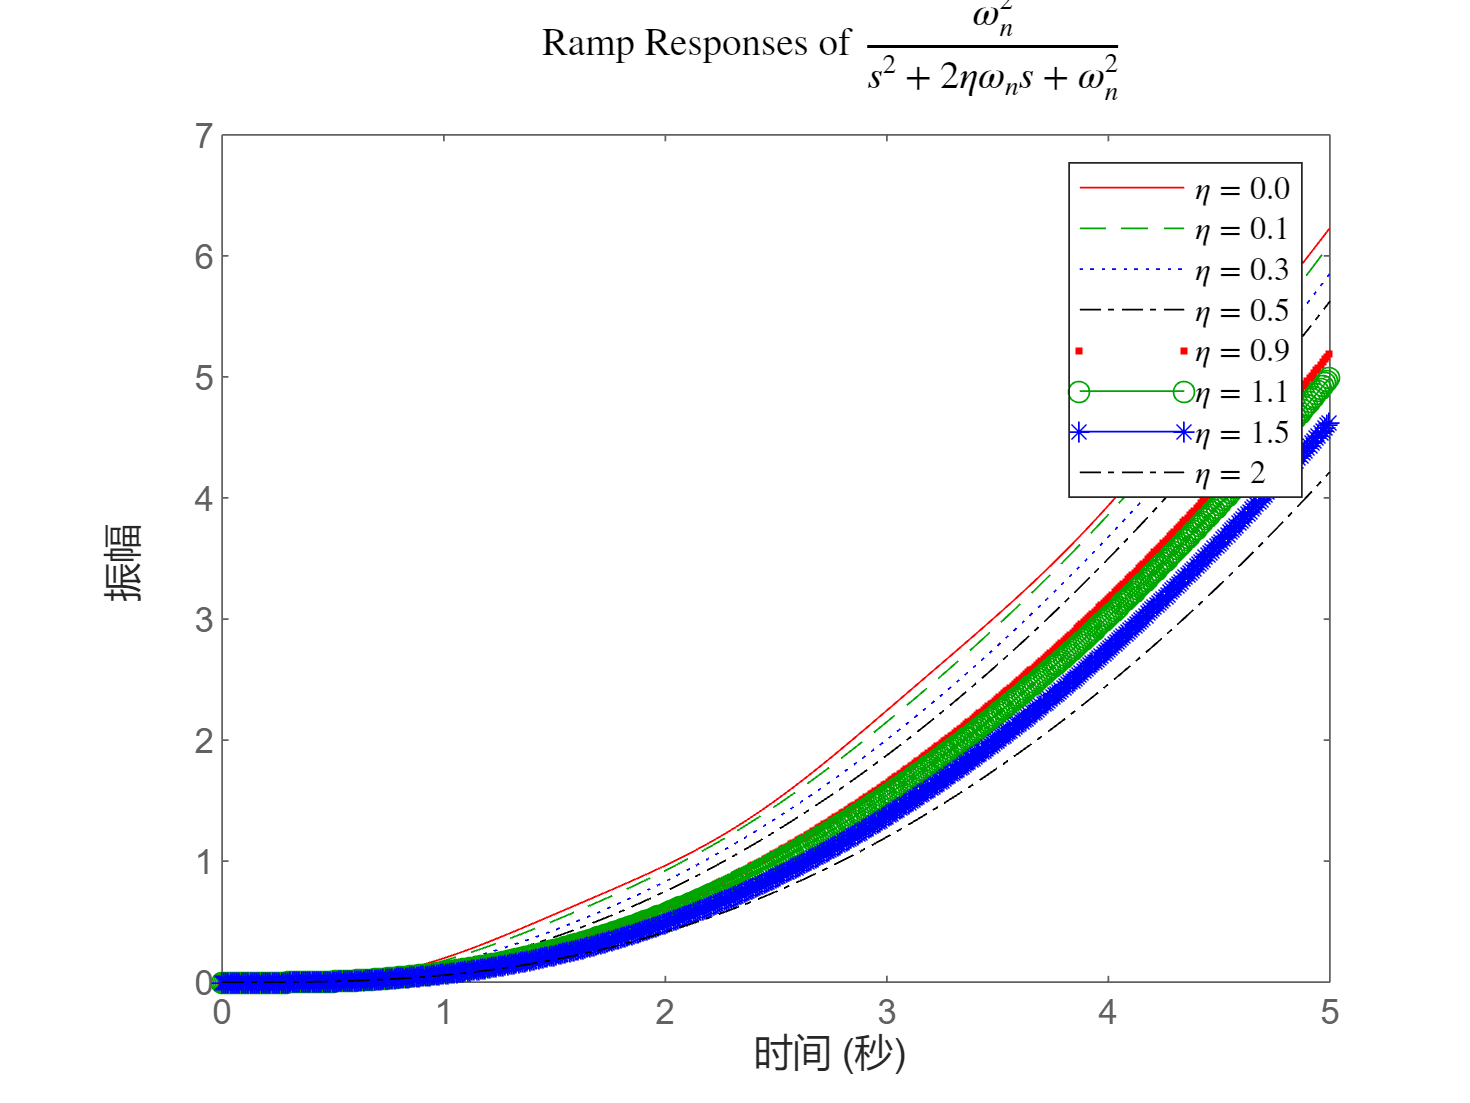


figure;
step(P0/(2*s^2),'r-', ...
     P1/(2*s^2),'g--', ...
     P2/(2*s^2),'b:', ...
     P3/(2*s^2),'k-.',...
     P4/(2*s^2),'r.',...
     P5/(2*s^2),'g-o',...
     P6/(2*s^2),'b-*',...
     P7/(2*s^2),'k-.',t);
hh = legend('$\eta = 0.0$','$\eta = 0.1$','$\eta = 0.3$','$\eta = 0.5$','$\eta = 0.9$','$\eta = 1.1$','$\eta = 1.5$','$\eta = 2$');
set(hh,'Interpreter','latex'); 

hh = title('Ramp Responses of $\frac{\omega_n^2}{s^2+ 2\eta \omega_n s+ \omega_n^2}$');
set(hh,'Interpreter','latex'); 

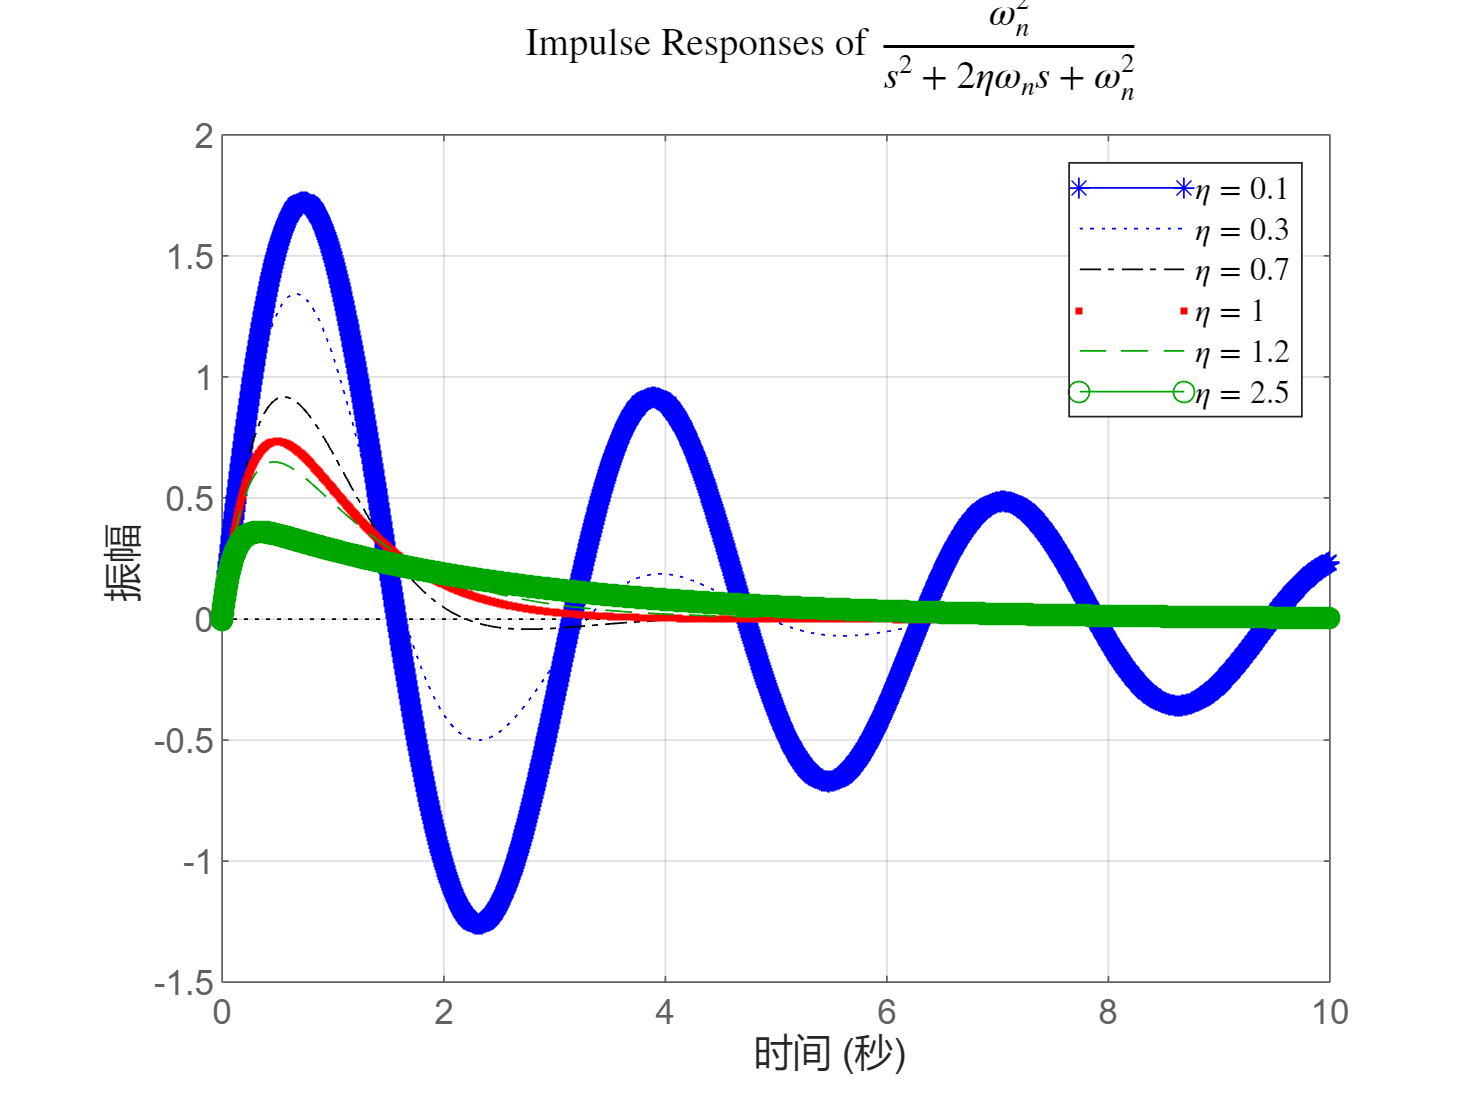

 


s = tf('s');
t = 0:0.001:10;

wn =2; eta=0.1;
Q1 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
 
wn =2; eta=0.3;
Q2 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =2; eta=0.7;
Q3 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =2; eta=1;
Q4 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =2; eta=1.2;
Q5 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =2; eta=2.5;
Q6 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

figure;
impulse( Q1,'b-*', ...
     Q2,'b:', ...
     Q3,'k-.',...
     Q4,'r.',...
     Q5,'g--',...
     Q6,'g-o',t);
hh = legend('$\eta = 0.1$','$\eta = 0.3$','$\eta = 0.7$','$\eta = 1$','$\eta = 1.2$','$\eta = 2.5$');
set(hh,'Interpreter','latex'); 

hh = title('Impulse Responses of $\frac{\omega_n^2}{s^2+ 2\eta \omega_n s+ \omega_n^2}$');
set(hh,'Interpreter','latex'); 
grid on;